clear variables; close all;clc
% unscented kalman filter example 2
% tracking of an airplane
% states = (distance, velocity, altitude) = (x, xdot, y)
% measures = (range, bearing) = (slant, elevation angle) = (r, etha)

addpath('../utilities');

% time step [s]
dt = 0.1;
endtime = 30;

% number of measures
n = endtime/dt+1;

% aircraft information

% it's between vor sensor A and vor sensor B
% the geometry is good so the performance are good
ac_pos = [100, 200];
% change aircraft position to (0, 0)
% the geometry is worse so the performances are worse
% ac_pos = [0, 0];
ac_vel = [10, 10];
ac_vel_std = 1e-3;

% sensor vor information
sa_pos = [-400, 0];
sb_pos = [400, 0];
std_noise = deg2rad(0.5);

% dimensions
dim_x = 4;
dim_z = 2;

% initial condition
% mean
x = [ac_pos(1), 1, ac_pos(2), 1]';
% covariance
P = eye(dim_x)*1e3;

% process noise covariance
Q(1:2,1:2) = [0.25*dt^4 0.5*dt^3;0.5*dt^3 dt^2]*1;
Q(3:4,3:4) = [0.25*dt^4 0.5*dt^3;0.5*dt^3 dt^2]*1;

% measure noise covariance
R = eye(dim_z) * std_noise^2;
  
% (non linear) state transition function
f = @(x, dt) f_cv_vor(x, dt);

% (non linear) measurement function
h = @(x) h_vor(x);

% sigma points deterministic sampling
alpha = 0.1;
beta = 2;
kappa = 0;

% data structures
x_posterior = zeros(dim_x,n);
x_prior = zeros(dim_x,n);
zs = zeros(dim_z,n);
xs = zeros(dim_x-2,n);

[Wm, Wc] = merwe_weights(alpha, beta, kappa, dim_x);

% filtering
for ii=1:n   
    % simulate new aircraft position (x, y)
    ac_pos = aircraft_simulator(ac_pos, ac_vel, ac_vel_std, dt);
    xs(:,ii) = ac_pos;
    
    % simulate vor measures
    z = measurement(sa_pos, sb_pos, ac_pos);
    z = z + randn(dim_z,1)*std_noise;
    
    % saving
    zs(:,ii) = z;
    
% 0) deterministic sampling from given mean and covariance (mass points)
    sigmas = merwe_points(alpha, kappa, dim_x, x, P);
    
% 1) predict:
    % (non linear) forward transition of the mass points (prediction)
    sigmas_f = f(sigmas, dt);
    % unscented transformation (computed mean and covariance of the mass
    % forwarded points)
    [x, P] = unscented_transform(sigmas_f, Wm, Wc, Q);
    x_prior(:,ii) = x;
    
% 2) update (correct)
    % (non linear) measurement space transformation of the mass forwarded points
    sigmas_h = h(sigmas_f);
    % unscented transformation (computed mean and covariance of the mass
    % forwarded points)
    [zp, Pz] = unscented_transform(sigmas_h, Wm, Wc, R);

    % cross covariance
    Pxz = (sigmas_f-x) * diag(Wc) * (sigmas_h-zp)';
    % kalman gain
    K = Pxz/(Pz);
    % residual
    y = z - zp;
    % posterior mean
    x = x + K*y;
    % posterior covariance
    P = P - K*Pz*K';
    x_posterior(:,ii) = x;
end

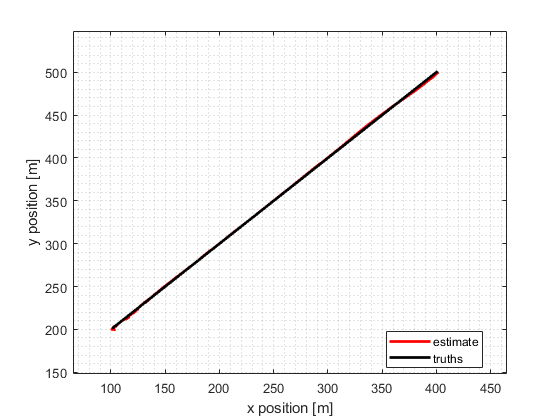

% plots

% 1 minute of measures
time = 0:dt:endtime;

figure
plot(x_posterior(1,:),x_posterior(3,:),'r','LineWidth',2);
hold on; grid minor;
plot(xs(1,:),xs(2,:),'k','LineWidth',2);
xlabel('x position [m]');
ylabel('y position [m]')
legend('estimate','truths','location','best')
xlim([65 465])
ylim([148 548])